1. Apply Gaussian noise to Figure 1, and then use the following to restore the image:

            i. Geometric Mean filter 

            ii. Harmonic Mean filter

            iii. Contra-harmonic Mean filter

% i. Geometric Mean filter 
clear
close all
clc

img = imread('Picture1.png');
j = imnoise(img, "gaussian");
I = rgb2gray(j);
I = im2double(I);

n = 3;

F = exp(imfilter(log(I), ones(n, n), 'replicate')).^(1/(n*n));
subplot(2, 3, 1), imshow(img), title('Original Image');
subplot(2, 3, 2), imshow(j), title('After apply noise');
subplot(2, 3, 3), imshow(F), title('GMF');

% ii. Harmonic Mean filter
clear
close all
clc

img = imread('Picture1.png');
j = imnoise(img, "gaussian");
I = rgb2gray(j);
I = im2double(I);
n = 3;
SF = (n*n)./imfilter(1./(I+eps), ones(n, n),'replicate');
subplot(2, 3, 1), imshow(img), title('Original Image');
subplot(2, 3, 2), imshow(j), title('After apply gaussian noise');
subplot(2, 3, 3), imshow(SF), title('HMF');

% iii. Contra-harmonic Mean filter
clear
close all
clc

img = imread('Picture1.png');
j = imnoise(img, "gaussian");
I = rgb2gray(j);
I = im2double(I);
n = 3;
order = 1;
SF = imfilter(I.^(order+1), ones(n, n),'replicate')./(imfilter(I.^(order), ones(n, n),'replicate')+eps);
subplot(2, 3, 1), imshow(img), title('Original Image');
subplot(2, 3, 2), imshow(j), title('After apply gaussian noise');
subplot(2, 3, 3), imshow(SF), title('CHMF');

2. i) Apply Gaussian noise to Figure 1, and then use the following order statistic filters to restore the image:

            i. Median filter 

             ii. Maximum filter 

            iii. Minimum filter

             iv. Midpoint filter

            v. Alpha-trimmed filter 

            vi. Trimmed filter

% i. Median filter 
clear
close all
clc

img = imread('Picture1.png');
j = imnoise(img, "gaussian");
I = rgb2gray(j);
I = im2double(I);
B = ordfilt2(I,5,ones(3,3));
subplot(2, 3, 1), imshow(img), title('Original Image');
subplot(2, 3, 2), imshow(j), title('After apply gaussian noise');
subplot(2, 3, 3), imshow(B), title('Median Filter');

% ii. Maximum filter
clear
close all
clc

img = imread('Picture1.png');
j = imnoise(img, "gaussian");
I = rgb2gray(j);
I = im2double(I);
B = ordfilt2(I,9,ones(3,3));
subplot(2, 3, 1), imshow(img), title('Original Image');
subplot(2, 3, 2), imshow(j), title('After apply gaussian noise');
subplot(2, 3, 3), imshow(B), title('Maximum Filter');

% iii. Minimum filter
clear
close all
clc

img = imread('Picture1.png');
j = imnoise(img, "gaussian");
I = rgb2gray(j);
I = im2double(I);
B = ordfilt2(I,1,ones(3,3));
subplot(2, 3, 1), imshow(img), title('Original Image');
subplot(2, 3, 2), imshow(j), title('After apply gaussian noise');
subplot(2, 3, 3), imshow(B), title('Minimum Filter');

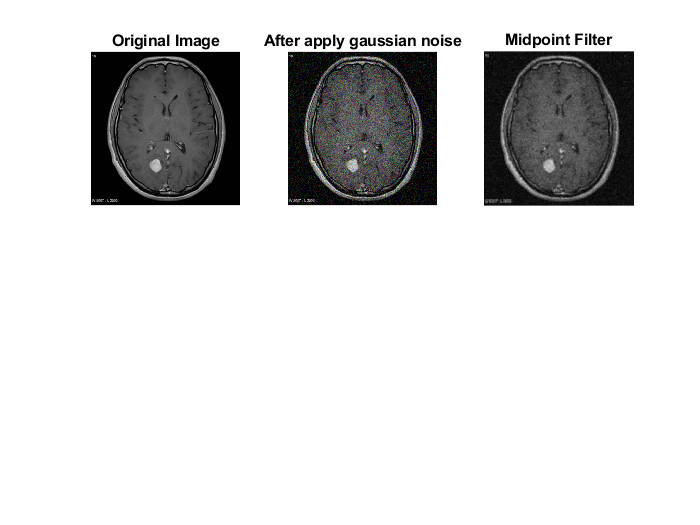

 % iv. Midpoint filter
clear
close all
clc

img = imread('Picture1.png');
j = imnoise(img, "gaussian");
I = rgb2gray(j);
I = im2double(I);
min = ordfilt2(I,1,ones(3,3));
max = ordfilt2(I,9,ones(3,3));
B = imlincomb(0.5,min,0.5,max);
midpointimage = B;
subplot(2, 3, 1), imshow(img), title('Original Image');
subplot(2, 3, 2), imshow(j), title('After apply gaussian noise');
subplot(2, 3, 3), imshow(B), title('Midpoint Filter');

% v. Alpha-trimmed filter 
clear
close all
clc

img = imread('Picture1.png');
j = imnoise(img, "gaussian");
I = rgb2gray(j);
I = im2double(I);
n = 3;
d = 2;
w = ones(n, n)/((n*n)-d);
B = imfilter(I, w,'replicate', 'same');
subplot(2, 3, 1), imshow(img), title('Original Image');
subplot(2, 3, 2), imshow(j), title('After apply gaussian noise');
subplot(2, 3, 3), imshow(B), title('Alpha-trimmed Filter');

% vi. Trimmed mean filter
clear
close all
clc

img = imread('Picture1.png');
j = imnoise(img, "gaussian");
I = rgb2gray(j);
I = im2double(I);
n = 3;
w = ones(n, n)/(n*n);
SF = imfilter(I, w, 'replicate')+eps;
subplot(2, 2, 1), imshow(img), title('Original Image');
subplot(2, 2, 2), imshow(j), title('After apply gaussian noise');
subplot(2, 2, 3), imshow(SF), title('TMF');

% a) Local/Regional Thresholding 
I = midpointimage;
T = graythresh(I);
a = im2bw(I, T);
subplot(2, 2, 1), imshow(I), title('Image from problem 3');
subplot(2, 2, 2), imshow(a), title('Local/Regional Thresholding');

% b) Global Thresholding
I = midpointimage;
BW = imbinarize(I,'global');
subplot(1,2,1);imshow(img);title('Original Image');
subplot(1,2,2);imshow(BW);title('Global Thresholding');

% c) Variable Thresholding
I = midpointimage;
[r c]=size (I);
output=zeros (r, c);
starts=floor (1:c/10:c);
ends = starts (2:length(starts));
ends=[ends c];
figure, imshow(I);
hold on;
for i = 1:10
    plot([ends(i) ends(i)], [1,r], 'w');
end
for i = 1:10
    temp = img(:, starts(i):ends(i));
    out(:, starts(i):ends(i))=im2bw(temp,graythresh(temp));
    plot([ends(i) ends(i)], [1,r], 'w');
end
subplot(2, 2, 1), imshow(I), title('Original Image');
subplot(2, 2, 2), imshow(out), title('Variable Thresholding Image');

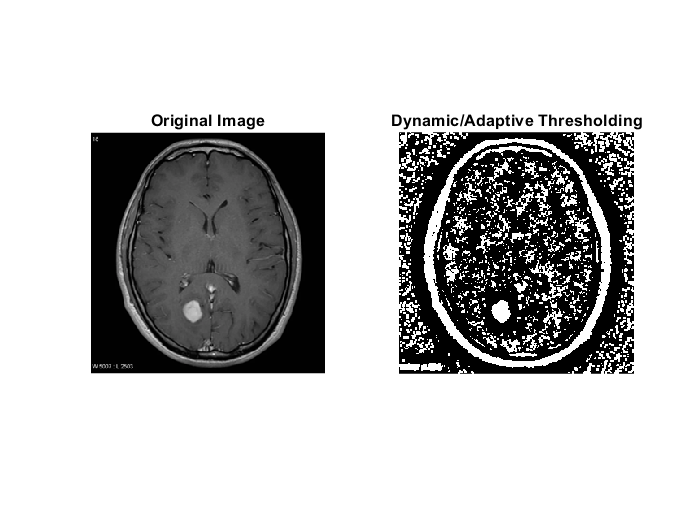

% d) Dynamic/Adaptive Thresholding
I = midpointimage;
BW = imbinarize(I,'adaptive');
subplot(1,2,1);imshow(img);title('Original Image');
subplot(1,2,2);imshow(BW);title('Dynamic/Adaptive Thresholding');

2. ii) Discontinuity approaches: 

            Edge Detection (Sobel, Canny, Prewitt)

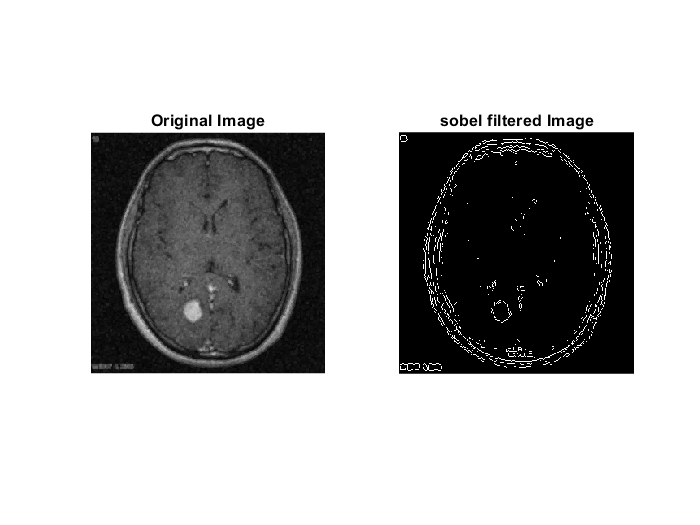

%a) 
img = midpointimage;
sobel = edge(img, 'Sobel');
subplot(1,2,1);imshow(img);title('Original Image');
subplot(1,2,2);imshow(sobel);title('sobel filtered Image');

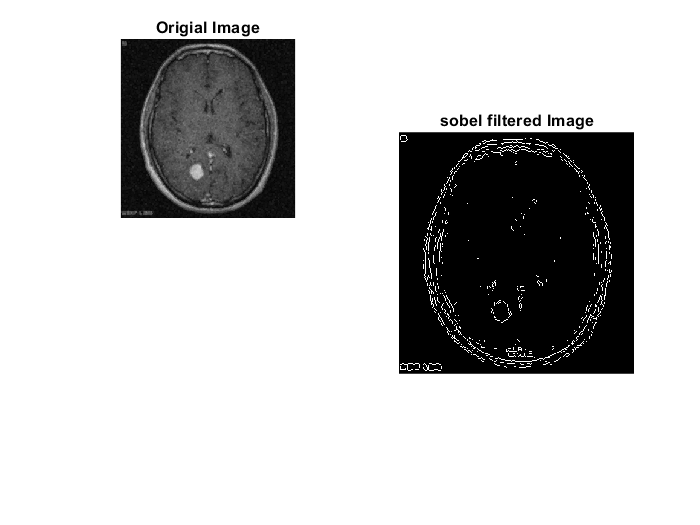

%b) 
img_canny=edge(img, 'Canny');
subplot(2,2,1);imshow(img);title('Origial Image'); 

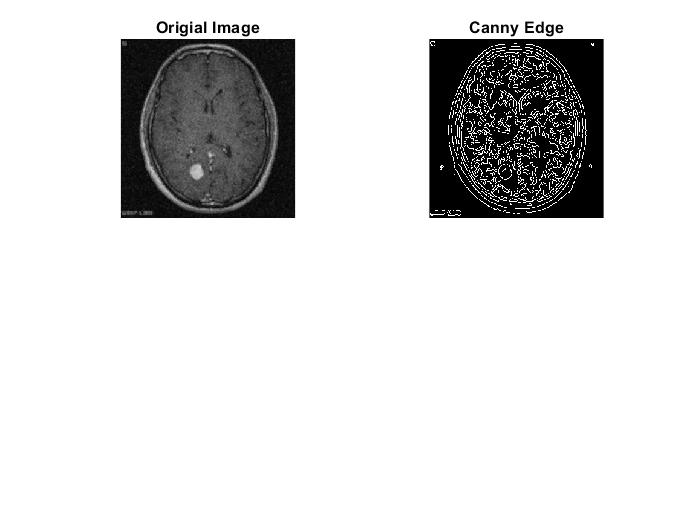

subplot(2,2,2);imshow(img_canny);title('Canny Edge');

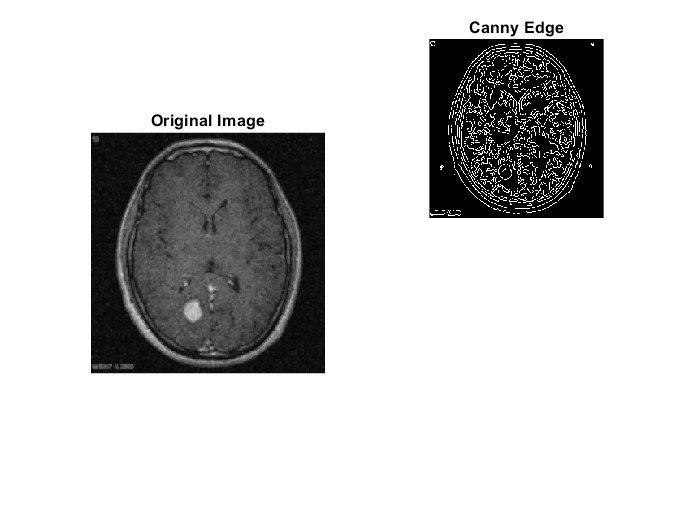

%c) 
prewitt = edge(img, 'Prewitt');
subplot(1,2,1);imshow(img);title('Original Image');

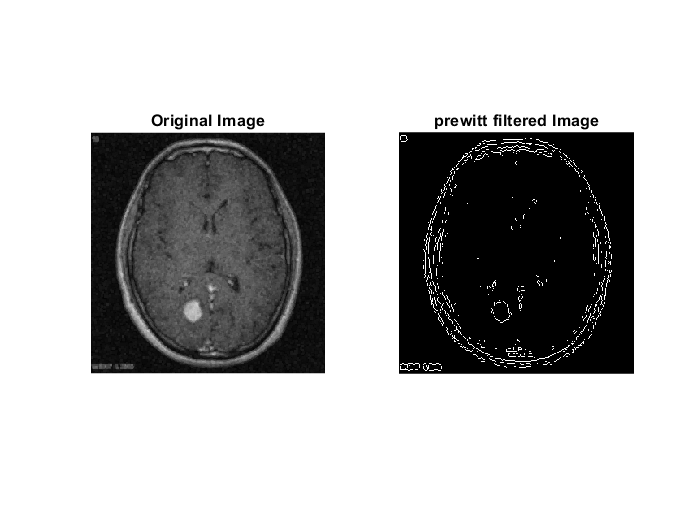

subplot(1,2,2);imshow(prewitt);title('prewitt filtered Image');

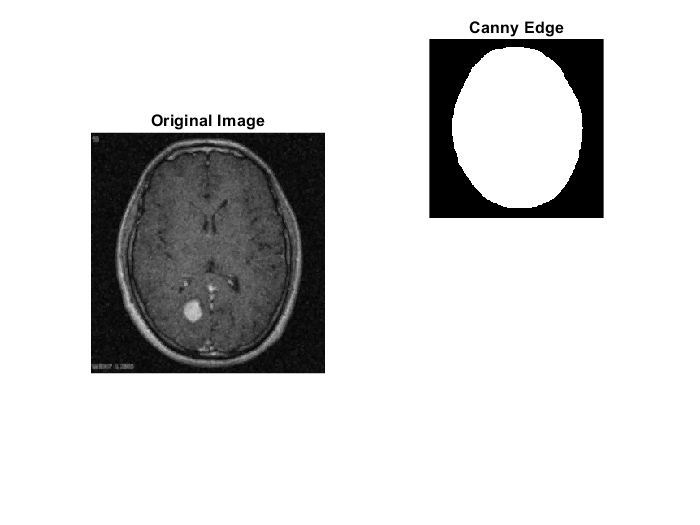

%c) 
prewitt = bwareaopen(imerode(imfill(imclose(edge(img, 'Prewitt'), strel('line', 3, 0)), 'holes'),strel(ones(3,3))),1500);

subplot(1,2,1);imshow(img);title('Original Image');

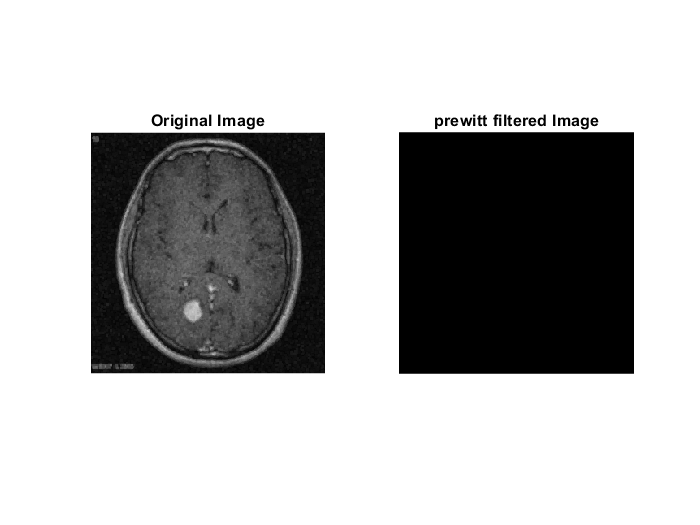

subplot(1,2,2);imshow(prewitt);title('prewitt filtered Image');